## Polymer Melt Flow Rate

Polymer properties such as density, melt index, and melt flow rate must be kept within tight specifications for each grade. This case study is to analyze polymer production data to predict melt flow rate. See full [problem statement](http://apmonitor.com/pds/index.php/Main/PolymerMeltFlowRate).

**PART 1: Analyze**

**Import Polymer MFR Data**

url = 'http://apmonitor.com/pds/uploads/Main/polymer_reactor.txt'

url = 'http://apmonitor.com/pds/uploads/Main/polymer_reactor.txt'

data = readtable(url)

data = 2564×9 table
          Var1          x513FC31103_pv    x513HC31114_5_mv    x513PC31201_pv    x513LC31202_pv    x513FC31409_pv    x513FC31114_5_pv    x513TC31220_pv    MFR
    ________________    ______________    ________________    ______________    ______________    ______________    ________________    ______________    ___

    0004-05-18 19:45        24857              0.153              30.415            79.658            50851             0.16399               80.4        3.4
    0004-05-18 21:45        25537              0.153              30.527            78.533            42230             0.12974             78.861        3.2
    0004-05-18 23:45        25689        

**Rename the columns** `['Time','C3=','H2R','Pressure','Level','C2=','Cat','Temp','MFR']`

data = renamevars(data, data.Properties.VariableNames, ["Time","C3=","H2R","Pressure","Level","C2=","Cat","Temp","MFR"])

data = 2564×9 table
          Time           C3=      H2R     Pressure    Level      C2=       Cat       Temp     MFR
    ________________    _____    _____    ________    ______    _____    _______    ______    ___

    0004-05-18 19:45    24857    0.153     30.415     79.658    50851    0.16399      80.4    3.4
    0004-05-18 21:45    25537    0.153     30.527     78.533    42230    0.12974    78.861    3.2
    0004-05-18 23:45    25689    0.153     30.356     78.843    45336       0.15    78.818    3.2
    0004-06-18 01:45    25099    0.153     30.894     79.174    43077    0.15154    79.023    3.1
    0004-06-18 03:45    24854     0.15     30.681     78.677    40404    0.12258    7

Create a new column for the natural log of (MFR) as `lnMFR`

data.lnMFR = log(data.MFR)

data = 2564×10 table
          Time           C3=      H2R     Pressure    Level      C2=       Cat       Temp     MFR    lnMFR 
    ________________    _____    _____    ________    ______    _____    _______    ______    ___    ______

    0004-05-18 19:45    24857    0.153     30.415     79.658    50851    0.16399      80.4    3.4    1.2238
    0004-05-18 21:45    25537    0.153     30.527     78.533    42230    0.12974    78.861    3.2    1.1632
    0004-05-18 23:45    25689    0.153     30.356     78.843    45336       0.15    78.818    3.2    1.1632
    0004-06-18 01:45    25099    0.153     30.894     79.174    43077    0.15154    79.023    3.1 

Use the `.describe()` function to get a summary of the data.

data = data(~any(ismissing(data),2),:);

statistics(data.("C3="))

ans = struct with fields:
    count: 968
     mean: 2.5408e+04
      std: 1.7873e+03
      min: 1.7929e+04
      max: 2.9896e+04
       Q1: 2.4339e+04
       Q2: 2.5304e+04
       Q3: 2.6556e+04


statistics(data.("H2R"))

ans = struct with fields:
    count: 968
     mean: 0.2065
      std: 0.0696
      min: 0
      max: 0.5280
       Q1: 0.1750
       Q2: 0.1900
       Q3: 0.2250


statistics(data.("Pressure"))

ans = struct with fields:
    count: 968
     mean: 30.7105
      std: 0.4896
      min: 26.9463
      max: 32.6743
       Q1: 30.4822
       Q2: 30.7204
       Q3: 30.9888


statistics(data.("Level"))

ans = struct with fields:
    count: 968
     mean: 77.7006
      std: 0.9730
      min: 74.7615
      max: 83.8417
       Q1: 77.0100
       Q2: 77.5726
       Q3: 78.2483


statistics(data.("C2="))

ans = struct with fields:
    count: 968
     mean: 4.5846e+04
      std: 1.2642e+04
      min: 1.0299e+04
      max: 8.4018e+04
       Q1: 3.7229e+04
       Q2: 4.5653e+04
       Q3: 5.4703e+04


statistics(data.("Cat"))

ans = struct with fields:
    count: 968
     mean: 0.1430
      std: 0.0449
      min: 0.0549
      max: 0.6465
       Q1: 0.1144
       Q2: 0.1368
       Q3: 0.1649


statistics(data.("Temp"))

ans = struct with fields:
    count: 968
     mean: 80.1639
      std: 0.9438
      min: 77.7601
      max: 91.5665
       Q1: 79.6129
       Q2: 80.0443
       Q3: 80.6212


statistics(data.("MFR"))

ans = struct with fields:
    count: 968
     mean: 9.6798
      std: 5.2079
      min: 1.5000
      max: 38
       Q1: 3.8000
       Q2: 11.9000
       Q3: 13.4000


statistics(data.lnMFR)

ans = struct with fields:
    count: 968
     mean: 2.0879
      std: 0.6413
      min: 0.4055
      max: 3.6376
       Q1: 1.3350
       Q2: 2.4765
       Q3: 2.5953


**PART II: Visualize**

Pair Plot

A pair plot shows the correlation between variables.

%%Plot everything except time column 

[~,AX] = plotmatrix(table2array(data(:,2:end)))

AX =   9×9 Axes array:

    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes
    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes    Axes


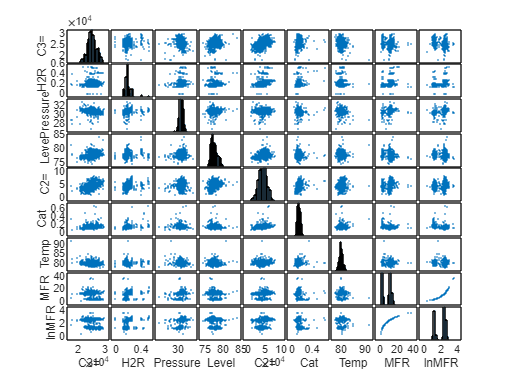


xlabel(AX(9,1),'C3=')
xlabel(AX(9,2),'H2R')
xlabel(AX(9,3),'Pressure')
xlabel(AX(9,4),'Level')
xlabel(AX(9,5),'C2=')
xlabel(AX(9,6),'Cat')
xlabel(AX(9,7),'Temp')
xlabel(AX(9,8),'MFR')
xlabel(AX(9,9),'lnMFR')

ylabel(AX(1,1),'C3=')
ylabel(AX(2,1),'H2R')
ylabel(AX(3,1),'Pressure')
ylabel(AX(4,1),'Level')
ylabel(AX(5,1),'C2=')
ylabel(AX(6,1),'Cat')
ylabel(AX(7,1),'Temp')
ylabel(AX(8,1),'MFR')
ylabel(AX(9,1),'lnMFR')




% for i = 1:n
%    for j = 1:n
%         if i == n 
%             xlabel(gca(j + n*(i-1)), data.Properties.VariableNames(j))
%         end 
% 
%         if j == 1
%             ylabel(gca(j+n*(i-1)), data.Properties.VariableNames(i))
%         end 
%    end
% end 

**Joint Plot**

A joint plot shows two variables, with the univariate and joint distributions. 

X = data.H2R

X =     0.1530
    0.1530
    0.1530
    0.1530
    0.1500
    0.1500
    0.1500
    0.1500
    0.1500
    0.1500


Y = data.lnMFR

Y =     1.2238
    1.1632
    1.1632
    1.1314
    1.1939
    1.1632
    1.2238
    1.2809
    1.3350
    1.3350


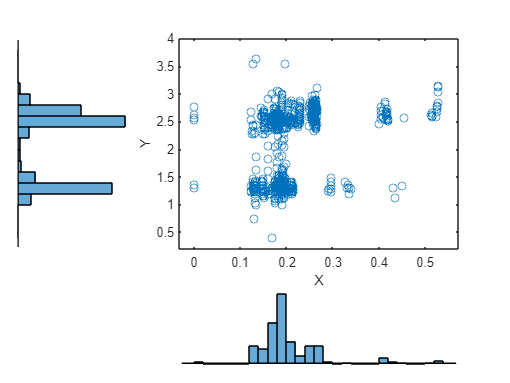


scatterhist(X,Y)

Try a count plot to show the number of binned samples of `lnMFR`

%%TODO::Cannot seem to create count plot w/o binning, and 
%%binning does not seem to work 

%%autobinning(data.lnMFR)

%%plotbins(databin,"lnMFR")

Create a correlation heat map

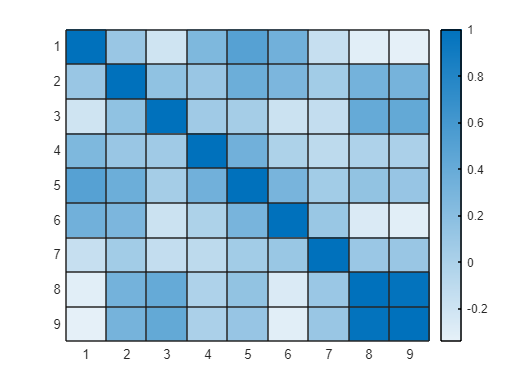

%%TODO:: check this, heat map does not exactly match with original 
%%but is laregly correct? 
correlation = corrcoef(table2array(data(:,2:end)));
figure;
heatmap(correlation)

## 3-Prepare Data

There are several graphical techniques to help detect outliers. A box or histogram plot shows outlying points.

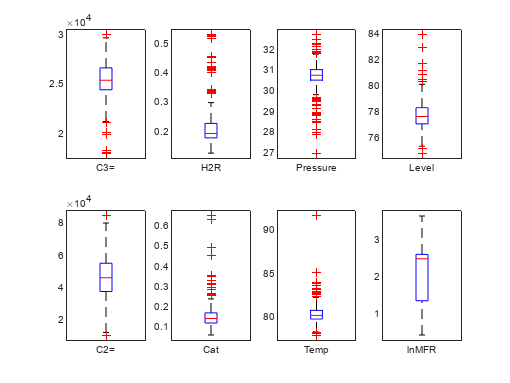

arr = table2array(data(:,2:end));

figure;
for i = 1:8
    subplot(2,4,i);
    c = data.Properties.VariableNames(i+1);
    boxplot(data.(c{1}),'Labels',c{1});
end
hold off

Remove outliers by removing select rows such as with:

data = data(data.H2R < 0.7,:);
data = data(data.H2R > 0.01,:);


to keep only values of `H2R` (Hydrogen to Monomer ratio) that are between 0.01 and 0.7.

Show the boxplot again to verify that the data set does not have outliers.

figure;
for i = 1:8
    subplot(2,4,i);
    c = data.Properties.VariableNames(i+1);
    boxplot(data.(c{1}),'Labels',c{1});
end
hold off

Remove MFR and keep only ln(MFR) as `lnMFR`. You can delete a column .....

data = removevars(data,("MFR"));

Scale Data

Scale data with the normalize, rescale or zscore.

N = normalize(data(:,2:end))

N = 962×8 table
      C3=         H2R       Pressure      Level         C2=           Cat         Temp       lnMFR  
    ________    ________    _________    _______    ___________    _________    ________    ________

    -0.30765    -0.80668     -0.60224     2.0069        0.39245      0.46365       0.247     -1.3461
    0.073194    -0.80668     -0.37338    0.85158       -0.28933     -0.29802     -1.3854     -1.4406
     0.15825    -0.80668     -0.72179     1.1699      -0.043686      0.15254     -1.4313     -1.4406
    -0.17215    -0.80668        0.375     1.5096       -0.22233      0.18679     -1.2142     -1.4901
    -0.30913    -0.85085    -0.060472     1.0001        -0.4337     -0.45716     -1.1974     -1.3927
    

S = rescale(table2array(data(:,2:end)))

S =     0.2958    0.0000    0.0004    0.0009    0.6052    0.0000    0.0010    0.0000
    0.3039    0.0000    0.0004    0.0009    0.5026    0.0000    0.0009    0.0000
    0.3058    0.0000    0.0004    0.0009    0.5396    0.0000    0.0009    0.0000
    0.2987    0.0000    0.0004    0.0009    0.5127    0.0000    0.0009    0.0000
    0.2958    0.0000    0.0004    0.0009    0.4809    0.0000    0.0009    0.0000
    0.3019    0.0000    0.0004    0.0009    0.3874    0.0000    0.0009    0.0000
    0.3052    0.0000    0.0004    0.0009    0.5065    0.0000    0.0009    0.0000
    0.3215    0.0000    0.0004    0.0009    0.5461    0.0000    0.0009    0.0000
    0.3250    0.0000    0.0004    0.0009    0.5895    0.0000    0.0009    0.0000
    0.3169    0.0000    0.0004    0.0009    0.5143    0.0000    0.0009    0.0000


Z = zscore(table2array(data(:,2:end)))

Z =    -0.3077   -0.8067   -0.6022    2.0069    0.3925    0.4636    0.2470   -1.3461
    0.0732   -0.8067   -0.3734    0.8516   -0.2893   -0.2980   -1.3854   -1.4406
    0.1583   -0.8067   -0.7218    1.1699   -0.0437    0.1525   -1.4313   -1.4406
   -0.1722   -0.8067    0.3750    1.5096   -0.2223    0.1868   -1.2142   -1.4901
   -0.3091   -0.8509   -0.0605    1.0001   -0.4337   -0.4572   -1.1974   -1.3927
   -0.0244   -0.8509   -0.5531    0.6060   -1.0550   -0.0576   -1.1731   -1.4406
    0.1323   -0.8509   -0.5930    0.8885   -0.2634    0.5277   -0.6382   -1.3461
    0.8969   -0.8509   -0.4195    1.1795   -0.0008    0.3862   -0.8240   -1.2570
    1.0637   -0.8509   -1.0310    1.2610    0.2879    0.3529   -1.7564   -1.1727
    0.6810   -0.8509   -1.0371    0.8943   -0.2121   -0.0337   -1.8101   -1.1727


Divide Data

Data is divided into train and test sets to separate a fraction of the rows for evaluating classification or regression models. A typical split is 80% for training and 20% for testing, although the range depends on how much data is available and the objective of the study.

The `train_test_split` is a function in `sklearn` for the specific purpose of splitting data into train and test sets.

trainRatio = .8

trainRatio = 0.8000

valRatio = 0

valRatio = 0

testRatio = .2

testRatio = 0.2000

[trainInd,valInd,testInd] = dividerand(length(data.Level),trainRatio,valRatio,testRatio)

trainInd =      3     5     6     7     8    11    14    16    17    21    22    25    26    27    28    29    30    31    32    33    34    35    37    38    40    41    42    43    45    46    47    48    49    50    51    52    53    54    55    56    58    59    60    61    62    63    64    67    68    69



valInd =

  1×0 empty double row vector



testInd =      1     2     4     9    10    12    13    15    18    19    20    23    24    36    39    44    57    65    66    71    73    75    82    85    94    95   102   114   116   118   122   124   125   126   130   132   137   141   153   154   158   161   167   168   173   189   191   192   199   200


x_train = data(trainInd, :)

x_train = 770×9 table
          Time           C3=      H2R     Pressure    Level      C2=       Cat       Temp     lnMFR 
    ________________    _____    _____    ________    ______    _____    _______    ______    ______

    0004-05-18 23:45    25689    0.153     30.356     78.843    45336       0.15    78.818    1.1632
    0004-06-18 03:45    24854     0.15     30.681     78.677    40404    0.12258    79.038    1.1939
    0004-06-18 05:45    25363     0.15     30.439     78.293    32549    0.14055    79.061    1.1632
    0004-06-18 07:45    25643     0.15     30.419     78.569    42558    0.16687    79.565    1.2238
    0004-06-18 09:45    27009     0.15     30.504     78.852    4

x_test = data(testInd, :)

x_test = 192×9 table
          Time           C3=      H2R     Pressure    Level      C2=       Cat        Temp     lnMFR 
    ________________    _____    _____    ________    ______    _____    ________    ______    ______

    0004-05-18 19:45    24857    0.153     30.415     79.658    50851     0.16399      80.4    1.2238
    0004-05-18 21:45    25537    0.153     30.527     78.533    42230     0.12974    78.861    1.1632
    0004-06-18 01:45    25099    0.153     30.894     79.174    43077     0.15154    79.023    1.1314
    0004-06-18 13:45    27307     0.15     30.204     78.931    49529     0.15901    78.512     1.335
    0004-06-18 15:45    26624     0.15     30.201     78.574

## 4-MFR Regression

The is objective is to minimize a loss function such as a sum of squared errors between the measured and predicted values:

Loss=∑ni=1(yi−zi)2

where `n` is the number of observations. Regression requires labelled data (output values) for training. Classification, on the other hand, can either be supervised (with `z` measurements, labels) or unsupervised (no labels, `z` measurements).

Linear Regression

There are many model forms such as linear, polynomial, and nonlinear. A familiar linear model is a line with slope `a` and intercept `b` with `y = a x + b`.

x = data.("H2R")

x =     0.1530
    0.1530
    0.1530
    0.1530
    0.1500
    0.1500
    0.1500
    0.1500
    0.1500
    0.1500


y = data.("lnMFR")

y =     1.2238
    1.1632
    1.1632
    1.1314
    1.1939
    1.1632
    1.2238
    1.2809
    1.3350
    1.3350


p1 = polyfit(x,y,1)

p1 =     3.0384    1.4558


Determine the slope and intercept that minimize the sum of squared errors (least squares) between the predicted `lnMFR` and measured `lnMFR` output using `H2R` as the input.

intercept = p1(1)

intercept = 3.0384

slope = p1(2)

slope = 1.4558


%x_columns = data.Properties.VariableNames(:,2:(end-1))
%z_columns = data.Properties.VariableNames(end)
x_mod = table2array(data(:,2:(end-1)));
y_mod = table2array(data(:,end));
mdl = fitlm(x_mod,y_mod);

display(mdl);

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)       -8.4247        2.3663    -3.5603    0.00038865
    x1             -0.0001143    1.0947e-05    -10.442    3.0607e-24
    x2                 2.9687       0.25216     11.773    5.6916e-30
    x3                0.31746       0.03383     9.3841    4.5024e-20
    x4              -0.027821      0.017069    -1.6299       0.10346
    x5             1.3414e-05    1.5733e-06     8.5262    5.8606e-17
    x6                 -4.787       0.38715    -12.365    1.1126e-32
    x7        

**Select Best Features**

Rank the features to determine the best set that predicts `lnMFR`.

[fit, scores] = fscchi2(x_mod,y_mod)

fit =      2     3     6     1     5     4     7


scores =    17.4522   51.1875   37.8246    5.0004    7.3333   20.2176    4.3778


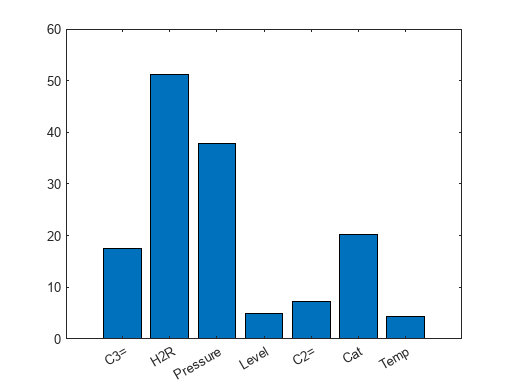

figure
bar(scores)
features = data.Properties.VariableNames(2:end-1);
set(gca, 'XTick', 1:length(features), 'XTickLabel', features)

**Machine Learning**

Machine learning is computer algorithms and statistical models that rely on patterns and inference. They perform a specific task without explicit instructions. Machine learned regression models can be as simple as linear regression or as complex as deep learning. 

xp = (-5:0.2:5);     
yp = (-5:0.2:5); 
    
[XP, YP] = meshgrid(xp, yp); 
    
x = table2array(x_train(:,{'H2R','Pressure'})); 
    
y = x_train.lnMFR; 
    
method = fitlm(x,y); 
    
zp = predict(method,[XP(:) YP(:)]); 
    
ZP = reshape(zp,size(XP)); 
    
r2 = method.Rsquared.Ordinary; 
    
fprintf('R^2: %0.4f\n', r2); 

R^2: 0.2488


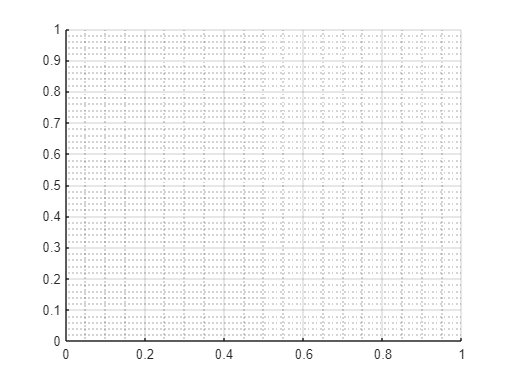

    
figure; 
    
ax = axes('XGrid', 'on', 'XMinorGrid', 'on', 'YGrid', 'on', 'YMinorGrid', 'on'); 

    
scatter3(x_train.H2R, x_train.Pressure, x_train.lnMFR, 100, c, 'filled'); 

Error using scatter3
Input arguments must be numeric, datetime, duration or categorical.

   
alpha(0.7); 

hold on; 

surf(XP,YP,ZP,'EdgeColor','none','FaceColor','interp','FaceAlpha',0.5); 

hold off; 

colormap(ax, 'parula'); 

xlabel('H2R'); 

ylabel('Pressure'); 

zlabel('lnMFR'); 

view(40,30); 

grid on; 


function r2 = graphfit(method, train, test, ds, z) 

    % create points for plotting surface 
    xp = -5:0.2:5; 
    yp = -5:0.2:5; 
    [XP,YP] = meshgrid(xp, yp); 

    X = train(:,{'H2R', 'Pressure'});  
    y = train.lnMFR; 

    model = method.fit(X,y); 
    [zp,~,~] = method.predict([XP(:),YP(:)]); 

    ZP = reshape(zp,size(XP,1),size(XP,2)); 
    r2 = method.score(test{:,{'H2R', 'Pressure'}},test.lnMFR); 
    disp(['R^2: ', num2str(r2)]); 

 

    figure; 
    ax = gca; 

    ax.View = [-35 45]; 
    ax.Box = 'on'; 
    ax.BoxStyle = 'full'; 
    hold on 

    ax.Scatter3 = scatter3(ds.H2R,ds.Pressure, ...
        ds.lnMFR,z,'filled','MarkerFaceAlpha',0.4); 

    surf(ax,XP,YP,ZP,'FaceAlpha',0.7); 
    colormap(ax,'coolwarm'); 
    colorbar(ax); 
    hold off 

end 
function statistics = statistics(data)
    statistics.count = numel(data); % count
    statistics.mean = mean(data); % mean
    statistics.std = std(data); % standard deviation
    statistics.min = min(data); % min
    statistics.max = max(data); % max
    statistics.Q1 = prctile(data,25); % 1st quartile (25th percentile)
    statistics.Q2 = prctile(data,50); % 2nd quartile (50th percentile) = median
    statistics.Q3 = prctile(data,75); % 3rd quartile (75th percentile)
end
